path_opt_09= readtable('traj_opt_09.csv');

path_opt_05= readtable('traj_opt_05.csv');

path_opt_04= readtable('traj_opt_04.csv');

path_opt_01= readtable('traj_opt_01.csv');


kappa_opt_09= readtable('kappa_opt_09.csv');

kappa_opt_05= readtable('kappa_opt_05.csv');

kappa_opt_04= readtable('kappa_opt_04.csv');

kappa_opt_01= readtable('kappa_opt_01.csv');


x_09= readtable('states_09.csv');
x_05= readtable('states_05.csv');
x_04= readtable('states_04.csv');
x_01= readtable('states_01.csv');
x_03= readtable('states_03.csv');

london_outer=readtable('london_outer.csv');

london_inner=readtable('london_inner.csv');

path_og= readtable('track_smooth.csv');

s_opt= readtable('length_opt.csv');

num_start=1;
num_end= 940;
plot_num= num_start:num_end;

s_cumsum= cumsum(s_opt.x_S_opt);

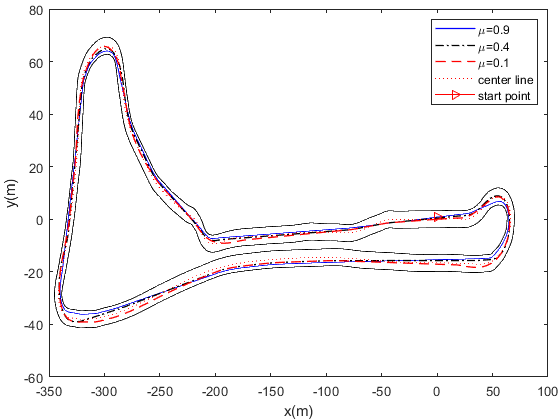

figure();
plot(path_opt_09.x_Traj_x, path_opt_09.traj_y, "LineWidth", 1.0, "Color", "blue")
hold on
% plot(path_opt_05.x_Traj_x(plot_num), path_opt_05.traj_y(plot_num), "LineWidth", 0.5, "Color", "red")
% hold on
plot(path_opt_04.x_Traj_x, path_opt_04.traj_y, "LineWidth", 1.0, "Color", "black", "LineStyle","-.")
hold on
plot(path_opt_01.x_Traj_x, path_opt_01.traj_y, "LineWidth", 1.0, "Color", "red", "LineStyle","--")
hold on
plot(path_og.x_Track_x, path_og.track_y, "Color", "red", "LineWidth", 0.5, "LineStyle",":")
hold on;
plot(path_opt_09.x_Traj_x(1), path_opt_09.traj_y(1), 'red', "marker",">")
hold on;
plot(london_outer.x_X, london_outer.y, 'black', 'LineWidth', 0.5)
hold on;
plot(london_inner.x_X, london_inner.y, 'black','LineWidth', 0.5)
hold off;
legend('\mu=0.9','\mu=0.4','\mu=0.1','center line', 'start point',  "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
set(gca,'LooseInset',get(gca,'TightInset'))

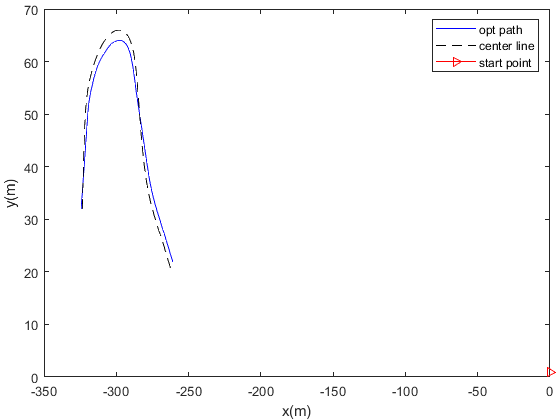

figure();
close;
plot(path_opt_09.x_Traj_x(plot_num), path_opt_09.traj_y(plot_num), 'blue', "LineWidth", 0.5)
hold on
plot(path_og.x_Track_x(plot_num), path_og.track_y(plot_num), 'black', "LineWidth", 0.5, "LineStyle","--")
hold on;
plot(path_opt_09.x_Traj_x(1), path_opt_09.traj_y(1), 'red', "marker",">")
% hold on;
% plot(london_outer.x_X, london_outer.y, 'black', 'LineWidth', 0.5)
% hold on;
% plot(london_inner.x_X, london_inner.y, 'black','LineWidth', 0.5)
% hold on;
% plot(path_x, path_y);
hold off;

%grid on; grid minor; 
legend('opt path', 'center line', 'start point',  "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
set(gca,'LooseInset',get(gca,'TightInset'))

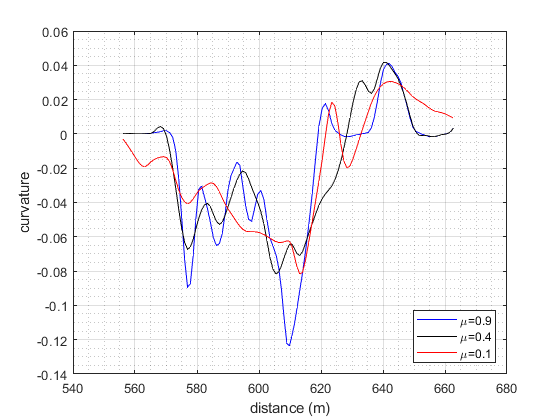

figure();
plot(s_cumsum(plot_num),kappa_opt_09.x_Kappa_opt(plot_num),"LineWidth", 0.5, "Color", "blue");
hold on;
% plot(s_cumsum(plot_num),kappa_opt_05.x_Kappa_opt(plot_num),"LineWidth", 0.5, "Color", "red");
% hold on;
plot(s_cumsum(plot_num),kappa_opt_04.x_Kappa_opt(plot_num), "LineWidth", 0.5, "Color", "black");
hold on;
plot(s_cumsum(plot_num),kappa_opt_01.x_Kappa_opt(plot_num), "LineWidth", 0.5, "Color", "red");
hold off;
legend('\mu=0.9','\mu=0.4','\mu=0.1', "Location", 'southeast')
grid on; grid minor;
xlabel('distance (m)');
ylabel('curvature');

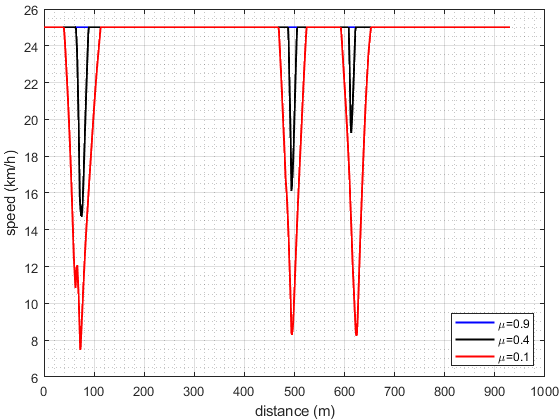

figure();
plot(s_cumsum(plot_num),x_09.Var1(plot_num)*(3.6), "LineWidth", 1.5, "Color", "blue");
hold on;
% plot(s_cumsum(plot_num),x_05.Var1(plot_num)*(3.6), "LineWidth", 1.0, "Color", "red");
% hold on;
plot(s_cumsum(plot_num),x_03.Var1(plot_num)*(3.6), "LineWidth", 1.5, "Color", "black");
hold on;
plot(s_cumsum(plot_num),x_01.Var1(plot_num)*(3.6), "LineWidth", 1.5, "Color", "red");
hold off;
legend('\mu=0.9','\mu=0.4','\mu=0.1', "Location", 'southeast')
grid on; grid minor;
xlabel('distance (m)');
ylabel('speed (km/h)');
set(gca,'LooseInset',get(gca,'TightInset'))